clc
clear all

% 0 = only negative pressure values
% 1 = only positive pressure values
% 2 = both pos&neg pressure values
positive_values = 2;

length_signal = 200;
start_signal = 200;

%load("C:\Users\emile\Downloads\pressure.mat")
%load("C:\Users\emile\Downloads\DOA.mat")

load("opt_truncated_mat_files\DOA.mat")
load("opt_truncated_mat_files\pressure.mat")

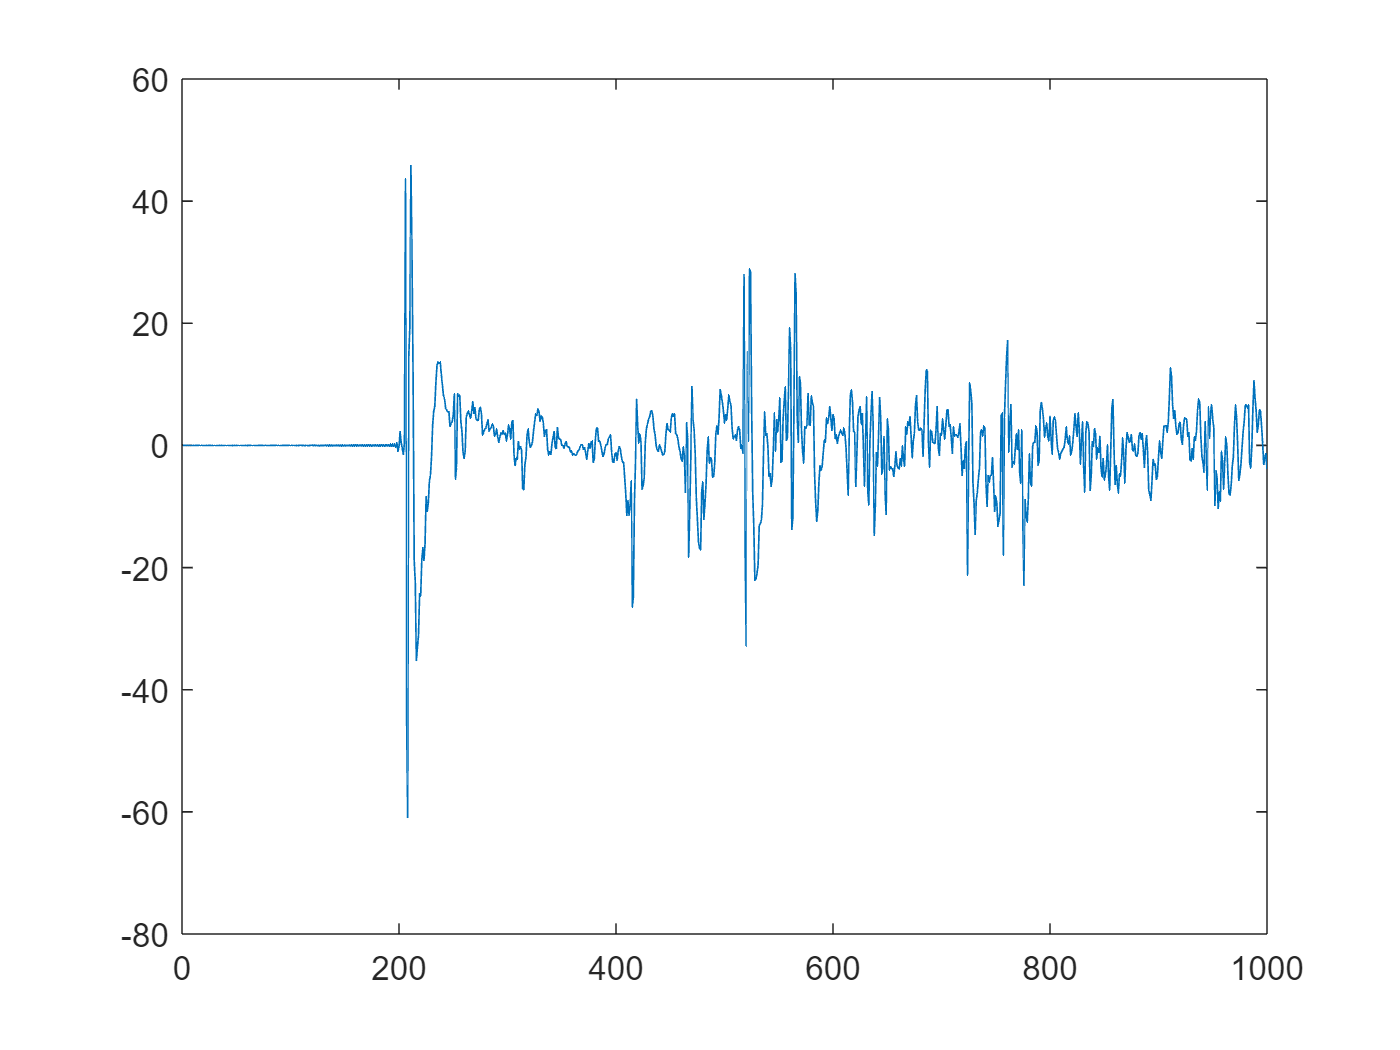

plot(P{1,1}(1:1000))

end_signal = start_signal + length_signal;

DOA1 = DOA{1,1}(start_signal:end_signal,:);
P1 = P{1,1}(start_signal:end_signal);
DOA3 = DOA{3,1}(start_signal:end_signal,:);
P3 = P{3,1}(start_signal:end_signal);

if positive_values == 1
    P1(P1 < 0) = 0;
    P3(P3 < 0) = 0;
elseif positive_values == 0
    P1(P1 > 0) = 0;
    P3(P3 > 0) = 0;
    P1 = abs(P1);
    P3 = abs(P3);
elseif positive_values == 2
    P1 = abs(P1);
    P3 = abs(P3);
end

norm(P1,1)

ans = 1.0877e+03

norm(P3,1)

ans = 1.1726e+03

clear DOA
clear P

number_of_discrete_positions = 12;
number_of_speakers = 2;

size_matrix = length(P1);
cost = zeros(size_matrix);

speed_of_sound = 343/48000;

% Optimal transport for measurement 1 and 3
% Cost matrix
for i=1:size_matrix
    for j=1:size_matrix
        cost(j,i) = power(norm(DOA1(i,1:3)*(speed_of_sound*i + speed_of_sound*start_signal) - (DOA3(j,1:3)*(speed_of_sound*j + speed_of_sound*start_signal))), 2);
    end
end

% Partial optimal transport matrix extend

distance_between_measurements = 0.4; % Distance between measurement 1 and 3 -> 40cm
epsilon = 1.05*power(norm(distance_between_measurements), 2);% increasing to 1.1-1.5 provide tolerance for imprecision

column = epsilon*ones(size_matrix,1); % Maybe infinity will cause an error
row = transpose(column);

cost_extended = [cost column; row Inf];

% See namegiving in paper RIR interpolation
a = P1;
b = P3;
a(a<0) = 0;
b(b<0) = 0;

% Check which solver is selected
cvx_solver

   Name     Status             Version   Location
--------------------------------------------------------
   SDPT3                       4.0       {cvx}\sdpt3
   SeDuMi   selected,default   1.3.4     {cvx}\sedumi



% Select sedumi solver if not yet selected
cvx_solver sedumi

% Save preferences for solver
cvx_save_prefs

Saving prefs...done.


% Partial Optimal Transport

cvx_begin
    cvx_precision low
    variable T_bar(size_matrix+1,size_matrix+1) nonnegative
    variable sig
    to_minimize = cvx(zeros(size_matrix+1,size_matrix+1));

    %T_bar(size_matrix+1,size_matrix+1) = 0;

    a_bar = [a ; norm(b,1) - sig];
    b_bar = [b ; norm(a,1) - sig];

    for i=1:size_matrix
        for j=1:size_matrix
            if i ~= size_matrix+1 && j ~= size_matrix+1
                to_minimize(i,j) = T_bar(i,j)*cost_extended(i,j);
            else
                to_minimize(i,j) = 0;
            end
        end
    end

    minimize( sum(sum(to_minimize)))
    subject to
        sig >= 0
        sig <= norm(a,1)
        sig <= norm(b,1)
        T_bar*ones(size_matrix+1, 1) == a_bar
        transpose(T_bar)*ones(size_matrix+1, 1) == b_bar
        sum(sum(T_bar(1:size_matrix,1:size_matrix))) == sig
        T_bar(size_matrix+1,size_matrix+1) == 0

        for i=1:size_matrix+1
            for j=1:size_matrix+1
                T_bar(i,j) >= 0
            end
        end
cvx_end

 
Calling SeDuMi 1.3.4: 82016 variables, 40804 equality constraints
   For improved efficiency, SeDuMi is solving the dual problem.
------------------------------------------------------------
SeDuMi 1.3.4 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
Split 405 free variables
eqs m = 40804, order n = 82422, dim = 82422, blocks = 1
nnz(A) = 81609 + 244020, nnz(ADA) = 40804, nnz(L) = 40804
Handling 810 + 0 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.46E+00 0.000
  1 :   3.41E+05 4.65E-01 0.000 0.3193 0.9000 0.9000  -0.96  1  1  7.3E+00
  2 :   7.88E+05 1.19E-02 0.000 0.0256 0.9900 0.9900  -0.37  1  1  3.6E-01
  3 :   8.64E+04 5.02E-03 0.000 0.4216 0.9000 0.9000   4.80  1  1  3.8E-02
  4 :   6.36E+04 4.30E-03 0.000 0.8564 0.9000 0.9000   2.18  1  1  2.7E-02
  5 :   3.28E+04 3.26E-03 0.000 0.7586 0.9000 0.9000   4.46  1  1  1.2E-02
  6 :   1.71

disp(sig)

  132.7745



T_ = T_bar;

T_bar = T_;
% moeten we dit wel doen, verliezen we dan niet gwn accuratie
for i=1:size_matrix+1
    for j=1:size_matrix+1
        if T_bar(i,j) < 1e-5
            T_bar(i,j) = 0;
        end
    end
end

norm(T_bar)

ans = 159.9908

if positive_values == 1
    save("opt_truncated_mat_files\Tbar_positive.mat", "T_bar")
elseif positive_values == 0
    save("opt_truncated_mat_files\Tbar_negative.mat", "T_bar")
elseif positive_values == 2
    save("opt_truncated_mat_files\Tbar.mat", "T_bar")
end